Energy-Based control of the Dumped Pendulum

$\ddot \phi + \kappa \dot \phi  - \sin \phi  = v  

$, dimensionlized equation

where  $\kappa = \frac \gamma {ml^2} \sqrt {\frac l g}$  ; $v = \frac u {mgl}$; 


$$E = mgl \left( \frac {\dot \phi^2} 2 + \cos \phi \right)$$


Angle measured from the top postion

Zero potential energy level goes through the pendulum's overhead

clear all
close all
% constants
gamma = 0.0;
m = 0.2;
g = 9.81;
L = 2;
global kappa;
kappa = gamma/(m*L^2) * sqrt(L/g); % dimensionless constant
global k; % proportionality coefficient for energy-based control
k = 1;
kappa

kappa = 0

PID-regulator estimated using LQR

% State-Space matreces
A = [0 1 0;
    1 -kappa 0;
     1 0 0];
B = [0; 1; 0];
% LQR matreces
Q = eye(3);
R = 1;
% solving Ricatti Equation
global K;
[X1,K,L1] = icare(A,B,Q,R);
K1 = K;

Pendulum Simulation

% initial condition
phi0 = 1;
dphi0 = 0.0;
I0 = 0; % integrator
Tsim = 50;
[t, phi] = ode45(@(t, y) RHS(t, y, 'Control', true), [0, Tsim], [phi0 dphi0 I0]); % x = [phi dphi I]

Plotting phase-space variables

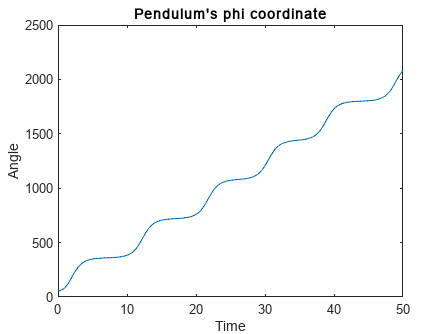

figure

plot(t, rad2deg(phi(:,1)));
xlabel("Time")
ylabel("Angle")
title("Pendulum's phi coordinate")

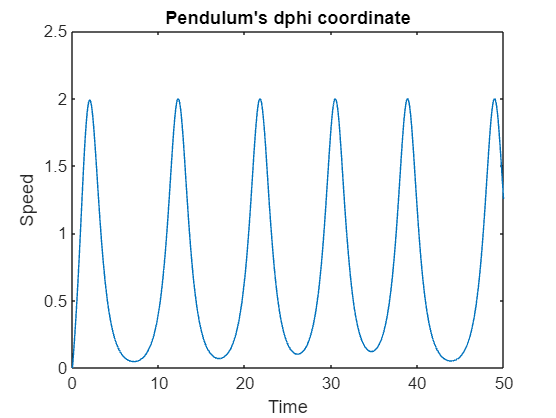

figure
plot(t, phi(:,2));
xlabel("Time")
ylabel("Speed")
title("Pendulum's dphi coordinate")

Phase-Portrait

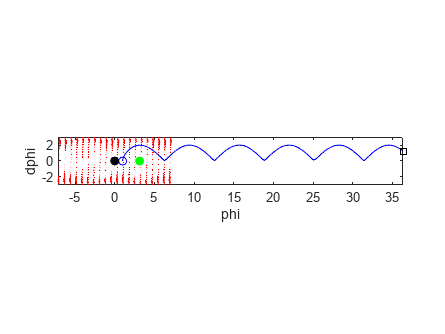

phi_ = linspace(-7, 7, 20);
dphi_ = linspace(-3, 3, 20);
[x1, x2] = meshgrid(phi_, dphi_);
u = zeros(size(x1));
v = zeros(size(x2));
time=0; % we want the derivatives at each point at t=0, i.e. the starting time
for i = 1:numel(x1)
    Yprime = RHS(time,[x1(i); x2(i); 0], 'Control', true);
    u(i) = Yprime(1);
    v(i) = Yprime(2);
end
quiver(x1, x2, u, v,'r'); figure(gcf)
xlabel('phi')
ylabel('dphi')
axis tight equal;
hold on
% plot particular solution
plot(phi(:,1), phi(:,2), 'Color', 'b')
plot(phi(1,1), phi(1,2),'bo') % starting point
plot(phi(end,1), phi(end,2),'ks') % ending point
plot(0, 0, 'ko', 'MarkerFaceColor', 'k') % unstable fixed point
plot(pi, 0, 'go', 'MarkerFaceColor', 'green') % stable fixed point
plot(-pi, 0)
hold off

Plotting Applyied Control

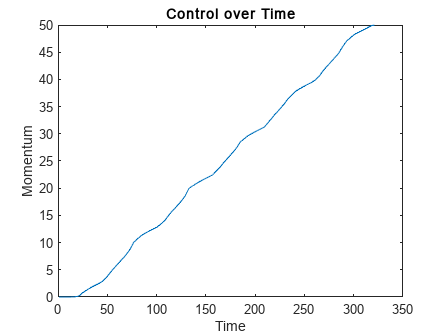

figure
%controlHyst = -K*phi';
Ed = 1; % desired energy
E = phi(:,2).^2/2 + cos(phi(:,1)); % current energy
e = E - Ed; % energy error
controlHyst = - k .* phi(:,2) .* e;
plot(t);
xlabel("Time")
ylabel("Momentum")
title("Control over Time")

Animation

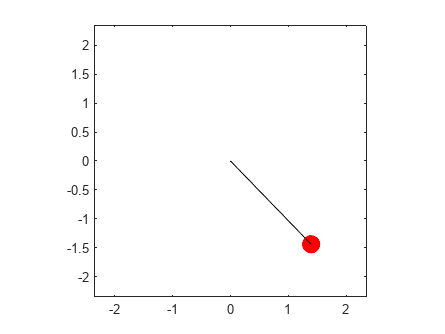

% spline approximation of x phi
t_unit = sqrt(L/9.81); % to show animation in the real world time
phis_ = spline(t*t_unit, phi(:,1));
phis = @(t) ppval(phis_, t);
% size of graphical elemnts
L_ = L; % pendulum length for visualization
R = 0.25*nthroot(m, 3);

% stop-motion animation using fanimator object
fanimator(@(t) plot([0; -L*sin(phis(t))], [0;  L*cos(phis(t))], 'Color', 'k'));
axis equal;
xlim([-0.2 - (L_ + R), 0.2 + L_ + R])
ylim([-0.2 - (L_+R), 0.2 + L_ + R])
hold on;
fanimator(@(t) rectangle('Position', [-L_*sin(phis(t)) - R, L_*cos(phis(t)) - R, 2*R, 2*R], 'Curvature', [1 1], 'FaceColor', 'r', 'EdgeColor','r'));
hold off;
playAnimation("FrameRate", 10, "AnimationRange", [0,Tsim*t_unit])

%playAnimation

function rhs = RHS(t, x, varargin)
    % default parameters
	p = inputParser; 
    p.addParameter('Control', true)
	p.parse(varargin{:});
    control = p.Results.Control;
    % globals
    global kappa;
    global k;
    global K;
    if control == false
        v = 0;
    else
        %v = -K*x;
%     elseif abs((mod(abs(x(1)/(2*pi)), 1) - 1/2)) > 0.1
        Ed = 1; % desired energy
        E = x(2)^2/2 + cos(x(1)); % current energy
        e = E - Ed; % energy error
        v = - k * x(2) * e;
%     else
        %v = -0.1*(pi - mod(abs(x(1)/(2*pi)),1));
    end

    % forming rhs
    rhs = [x(2);  sin(x(1)) - kappa*x(2) + v; x(1)];
end